# Image Filtering

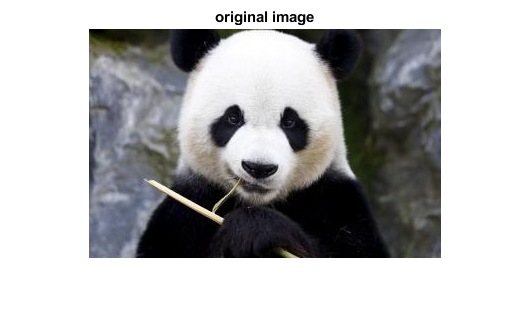

im = imread('panda.jpg');
figure; imshow(im);title('original image')

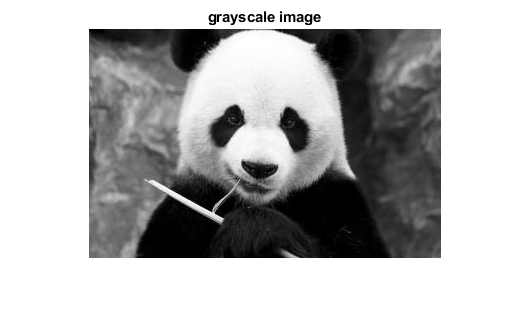

im = rgb2gray(im);
figure; imshow(im);title('grayscale image')

im = im2double(im); % convert image to double

## Low-Pass Filtering

Low pass filters passes low frequency signals and blocks high frequency signals

### Mean Filter

Mean filtering is simply replacing each pixel value in an image with the mean (average) value of its neighbors, including itself

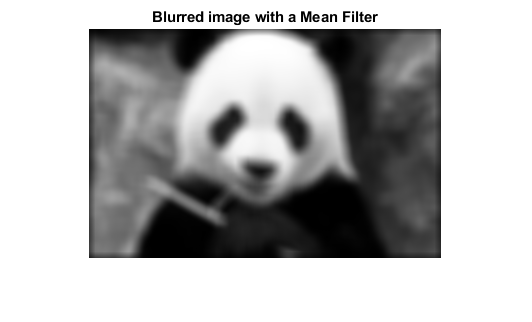

h_box = fspecial('average',[13 13]);
im_box = imfilter(im,h_box,'conv');
figure; imshow(im_box); title('Blurred image with a Mean Filter');

### Gaussian Filter

Gaussian filtering (g) is used to blur images and remove noise and detail. Gaussian distribution in 2D has the form:$g\left(u,v,\sigma \right)=\frac{1}{2\pi \sigma^2 }e^{-\frac{u^2 +v^2 }{\sigma^2 }}$where $\sigma$ is spread parameter.

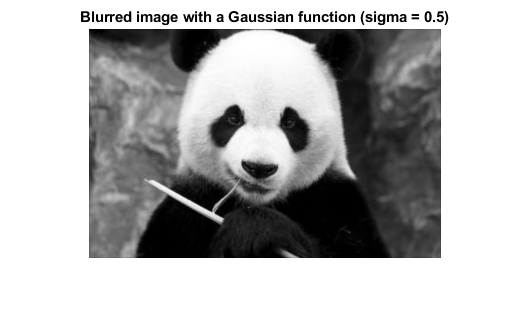

h_gaus1 = fspecial('gaussian',[13 13],0.5);
h_gaus2 = fspecial('gaussian',[13 13],3);
im_gaus1 = imfilter(im,h_gaus1,'conv');
im_gaus2 = imfilter(im,h_gaus2,'conv');
figure();imshow(im_gaus1);title('Blurred image with a Gaussian function (sigma = 0.5)');

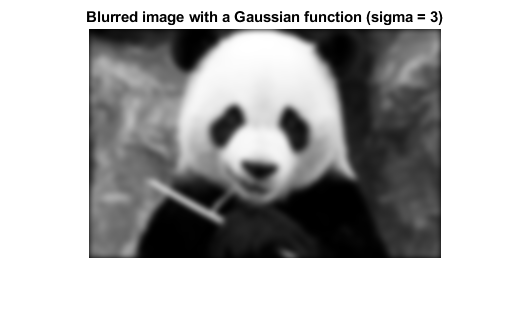

figure();imshow(im_gaus2);title('Blurred image with a Gaussian function (sigma = 3)')

## High-Pass Filtering

A high-pass filter can be used to make an image appear sharper. High pass filters passes high frequency signals and blocks low frequency signals.

### Laplacian Filter

The Laplacian *L(x,y)* of an image with pixel intensity values *I(x,y)* is given by


$$L\left(x,y\right)=\frac{\delta^2 I}{\delta x^2 }+\frac{\delta^2 I}{\delta y^2 }$$


Since the input image is represented as a set of discrete pixels, we have to find a discrete convolution kernel that can approximate the second derivatives in the definition of the Laplacian. Two commonly used small kernels are:

h_lap1 = [0 -1 0; -1 4 -1; 0 -1 0];
h_lap2 = [-1 -1 -1; -1 8 -1; -1 -1 -1];

Using one of these kernels, the Laplacian can be calculated using standard convolution methods:

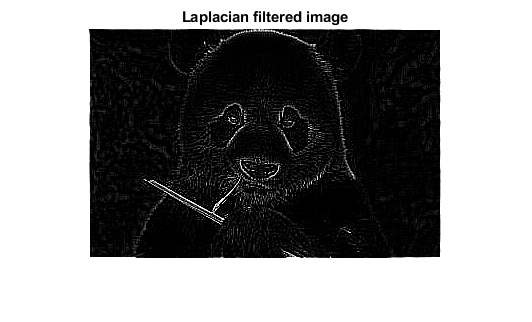

im_lap = imfilter(im,h_lap2,'conv');
figure(); imshow(im_lap); title('Laplacian filtered image');

We can sharpen the input image by using laplacian filtered image as follows:

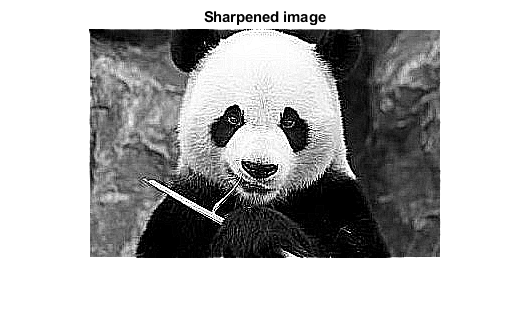

im_sharp = im + im_lap;
figure(); imshow(im_sharp); title('Sharpened image');

If we normalize laplacian filtered and  sharpened images result will be better:

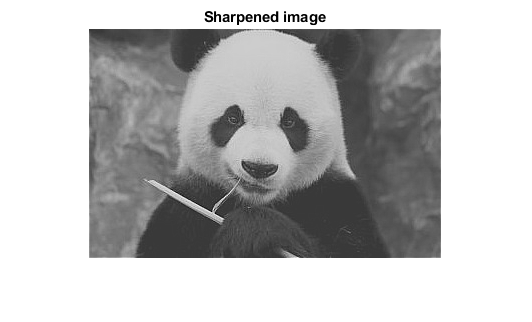

% Normalize the laplacian filtered image
minL = min(im_lap(:));
maxL = max(im_lap(:));
im_lap = (im_lap - minL) / (maxL - minL);
% Adding to original image
im_sharp = im + im_lap;
% Normalize the sharpened image
minS = min(im_sharp(:));
maxS = max(im_sharp(:));
im_sharp = (im_sharp - minS) / (maxS - minS);
figure(); imshow(im_sharp); title('Sharpened image');

### Edge Detection Filters

The Sobel, Prewitt, or Roberts methods find the edges by approximating the gradient magnitude of the image. (We will make an example with Sobel Filter. See the Prewitt and Roberts filters.)

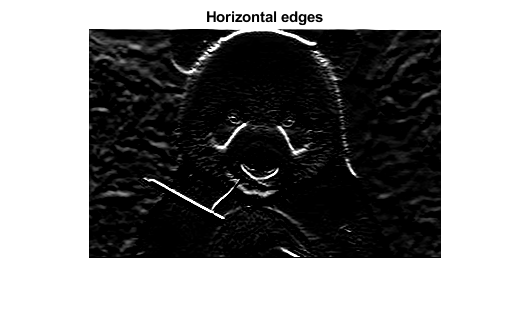

h_sobel = [1 2 1; 0 0 0; -1 -2 -1]; % or h_sobel = fspecial('sobel');
im_sobelH = imfilter(im, h_sobel, 'conv');
im_sobelV = imfilter(im, h_sobel', 'conv');
figure(); imshow(im_sobelH); title('Horizontal edges');

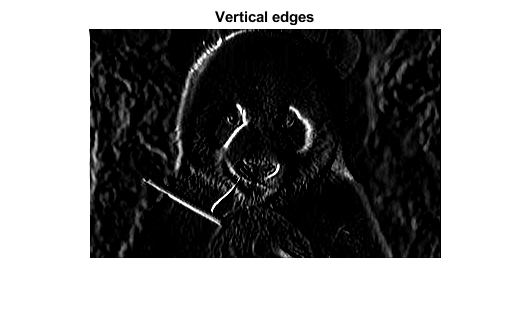

figure(); imshow(im_sobelV); title('Vertical edges');

An image gradient is a directional change in the intensity or color in an image. We can find  gradient magnitude and direction of an image by using its vertical and horizontal edges

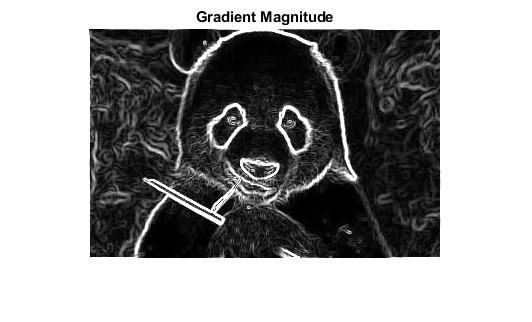

[gradient_mag, gradient_dir] = imgradient(im_sobelH, im_sobelV);
%You can obtain same result by: 
%[gradient_mag, gradient_dir] = imgradient(im, 'sobel');
figure();imshow(gradient_mag);title('Gradient Magnitude');

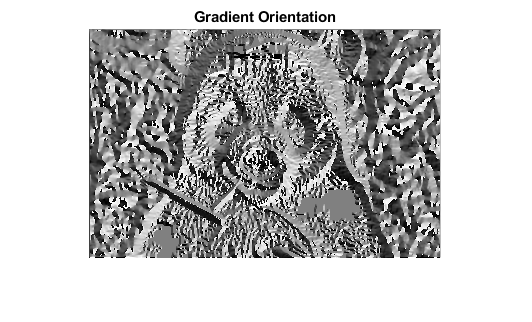

figure();imshow(gradient_dir,[]);title('Gradient Orientation');

## Other Filters

### Motion Filter

Motion filter approximates, once convolved with an image, the linear motion of a camera. `len` specifies the length of the motion and `theta` specifies the angle of motion in degrees in a counter-clockwise direction. 

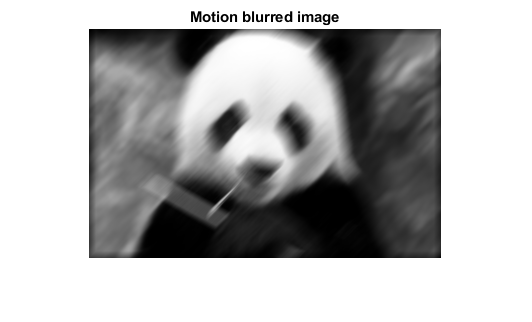

h_motion = fspecial('motion',20,45);
im_motion = imfilter(im, h_motion,'conv');
figure(); imshow(im_motion); title('Motion blurred image');